# 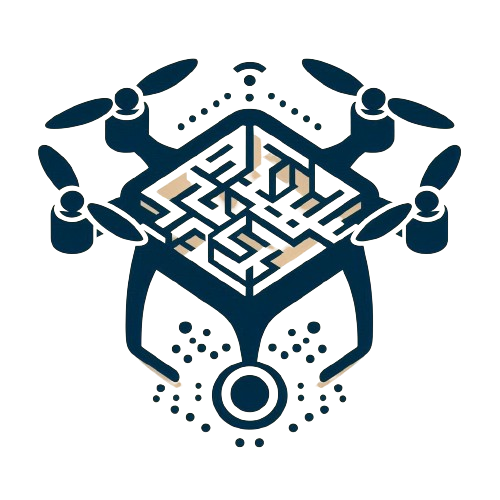

LiDflAIR    Tonelli-Zumerle

# Statistics simulations

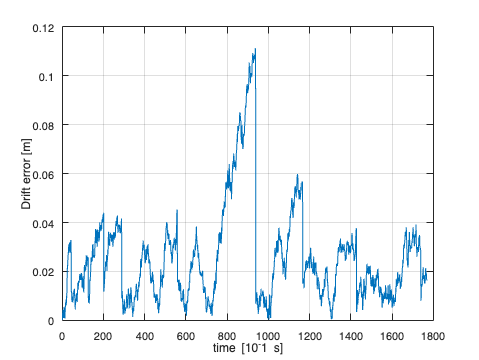

for i=1:1:count
    drift_error(i) = norm(Drone.Drone_1.RRT.all_positions_drift(i,:) - Drone.Drone_1.RRT.all_positions(i,:));
end
plot(1:1:count,drift_error);
xlabel('time [10^-1 s]');
ylabel('Drift error [m]');
grid on;


drift_error_max = max(drift_error)

drift_error_max = 0.1113

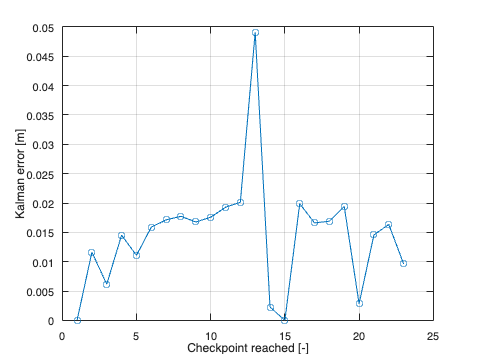


for i=1:1:(Drone.Drone_1.count_pos -1)
    kalman_error(i) = norm(Drone.Drone_1.map(i,:) - Drone.Drone_1.kalman_map(i,:));
end
plot(1:1:(Drone.Drone_1.count_pos -1),kalman_error,'o-')
xlabel('Checkpoint reached [-]');
ylabel('Kalman error [m]');
grid on;

All the previous simulations results in terms of coverage ratio are collected and plotted

Data saved from each simulation consist in |n° of drones | time of exploration | % map discovered

% Collects all simulation results from its root
sim_matrix = [];

directory = 'Simulation_data';

fileList = dir(fullfile(directory, 'data_sim_*.txt'));

for k = 1:length(fileList)
    fileName = fullfile(directory, fileList(k).name);
    data_sim = dlmread(fileName, ';');
    sim_matrix = [sim_matrix; data_sim];
end

Plot the data obtained to visualize the trend

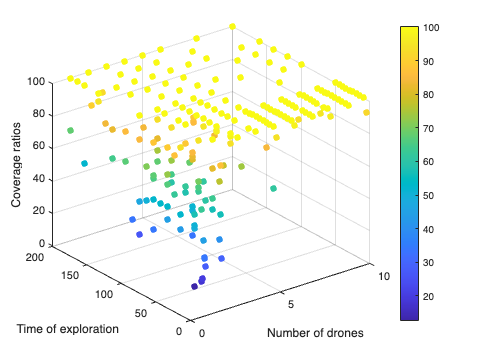

% Seprate the data
x = sim_matrix(:, 1);
y = sim_matrix(:, 2);
z = sim_matrix(:, 3);

% Plot the data
s = scatter3(x, y, z, [], z, 'filled');
colorbar;
xlabel('Number of drones');
ylabel('Time of exploration');
zlabel('Coverage ratios');
zlim([0 100]);


% Generate a single row for each of the combination discovered: if there
% are more, compute the average of the coverage ratio
[uniqueGroups, ~, idx] = unique(sim_matrix(:, 1:2), 'rows');
meanValues = accumarray(idx, sim_matrix(:, 3), [], @mean);

% Reorder the data in a new matrix
mean_matrix = [uniqueGroups, meanValues];
x = mean_matrix(:, 1);
y = mean_matrix(:, 2);
z = mean_matrix(:, 3);

% Generate a fit model able to approximate the trend. Chosen a fourth order
ft = fittype('poly44'); 
fo = fitoptions('Method','LinearLeastSquares','Normalize','on');
fitresult = fit([x, y], z, ft, fo)

     Linear model Poly44:
     fitresult(x,y) = p00 + p10*x + p01*y + p20*x^2 + p11*x*y + p02*y^2 + p30*x^3 
                    + p21*x^2*y + p12*x*y^2 + p03*y^3 + p40*x^4 + p31*x^3*y 
                    + p22*x^2*y^2 + p13*x*y^3 + p04*y^4
       where x is normalized by mean 5.161 and std 2.968
       and where y is normalized by mean 72.98 and std 60.33
     Coefficients (with 95% confidence bounds):
       p00 =       100.1  (96.56, 103.6)
       p10 =   -0.002309  (-3.825, 3.82)
       p01 =      -2.355  (-7.133, 2.423)
       p20 =      -5.587  (-11.16, -0.01893)
       p11 =      -3.616  (-7.637, 0.4056)
       p02 =    -0.08928  (-4.326, 4.147)
       p30 =       6.806  (4.784, 8.828)
       p21 =       4.026  (2.11, 5.941)
       p12 =       2.266  (-0.2644, 4.796)
       p03 =       4.249  (0.3112, 8.187)
       p40 =      -2.378  (-4.621, -0.1351)
       p31 =      -1.068  (-2.865, 0.7281)
       p22 =    -0.01562  (-1.673, 1.642)
       p13 =     -0.8693  (-2.473, 0.7346)


coeffs = coeffvalues(fitresult)'

coeffs =   100.0621
   -0.0023
   -2.3551
   -5.5871
   -3.6159
   -0.0893
    6.8061
    4.0257
    2.2660
    4.2492



% Residual calculus
zFit = feval(fitresult, x, y);
residuals = z - zFit;

% Information about the fitting obtained
SS_residual = sum(residuals.^2);
SS_total = sum((z - mean(z)).^2);
R2 = 1 - (SS_residual / SS_total);
mse = mean(residuals.^2);

fprintf('R^2: %f\n', R2);

R^2: 0.840896


fprintf('Mean Squared Error (MSE): %f\n', mse);

Mean Squared Error (MSE): 47.993486


fprintf('Root Mean Squared Error (MSE): %f\n', sqrt(mse));

Root Mean Squared Error (MSE): 6.927733


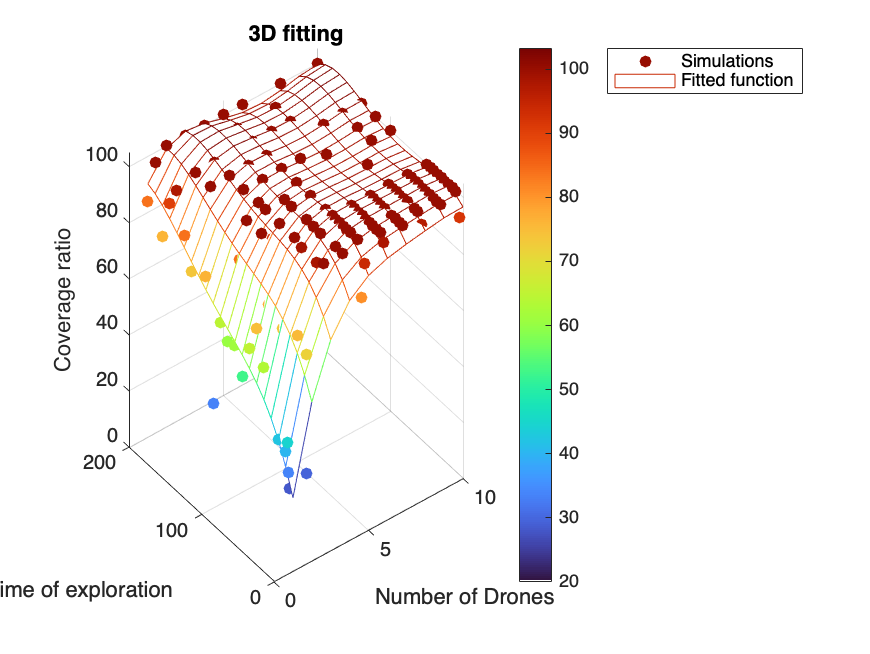


% Plot dei dati originali
figure;
scatter3(x, y, z, [], z, 'filled');
cmap = turbo(256);
cmap(1, :) = 1;
colormap(cmap);
colorbar;
zlim([0 105]);
hold on;

% Grid creation for visualization
[x_grid, y_grid] = meshgrid(1:1:10,0:10:200);
z_fit = feval(fitresult, x_grid, y_grid);
% Plot of the fitted curve
mesh(x_grid, y_grid, z_fit);
xlabel('Number of Drones');
ylabel('Time of exploration');
zlabel('Coverage ratio');
title('3D fitting');
legend('Simulations', 'Fitted function');
hold off;

#### Estimate the coverage reatio for given number of drones and time of simulation

Select the number of drones to develope and the wanted time to explore to predict the coverage ratio

drone =3

drone = 3

time_of_simulation =30

time_of_simulation = 30

coverage_ratio_estimated = min(fitresult(drone, time_of_simulation), 100);

disp(['The estimated value of the coverage ratio of the map is: ', num2str(round(coverage_ratio_estimated)), ' %']);                 

The estimated value of the coverage ratio of the map is: 89 %
